load HCVEgyptData.mat
disp(HCV)

    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       BaselinehistologicalGrading    Baselinehistologicalstaging
    ___    ______    ___    _____    ________

class(HCV)

ans = 'table'

size(HCV)

ans =         1385          29


sum(sum(ismissing(HCV)))

ans = 0

rmmissing(HCV)

ans = 1385×29 table
    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       BaselinehistologicalGrading    Baselinehistologicalstaging
    ___    ______    ___    _____

MODEL OUTPUTS 

Histological results --> column 28,29

MODEL INPUTS

RNA based values --> column 23, 24, 25, 26, 27

Serum biomarkers ---> column 11 to 22

HCV_array=table2array(HCV)

HCV_array =           56           1          35           2           1           1           1           2           2           2        7425     4248807          14      112132          99          84          52         109          81           5           5           5      655330      634536      288194           5           5          13           2
          46           1          29           1           2           2           1           2           2           1       12101     4429425          10      129367          91         123          95          75         113          57         123          44       40620      538635      637056      336804       31085           4           2
          57           1          33           2           2           2           2           1           1           1        4178     4621191          12      151522         113          49          95         107         116           5           5           5      571148      661346  

## Data Cleaning

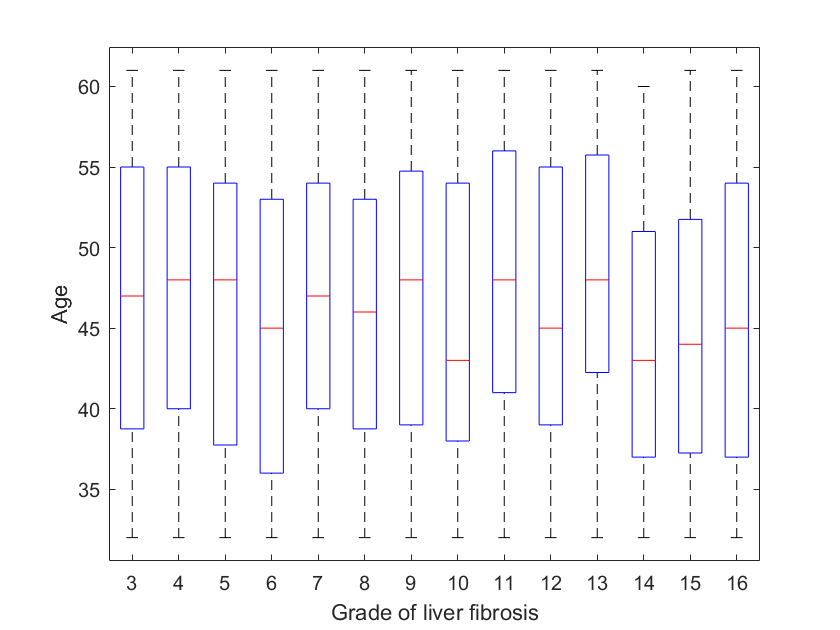

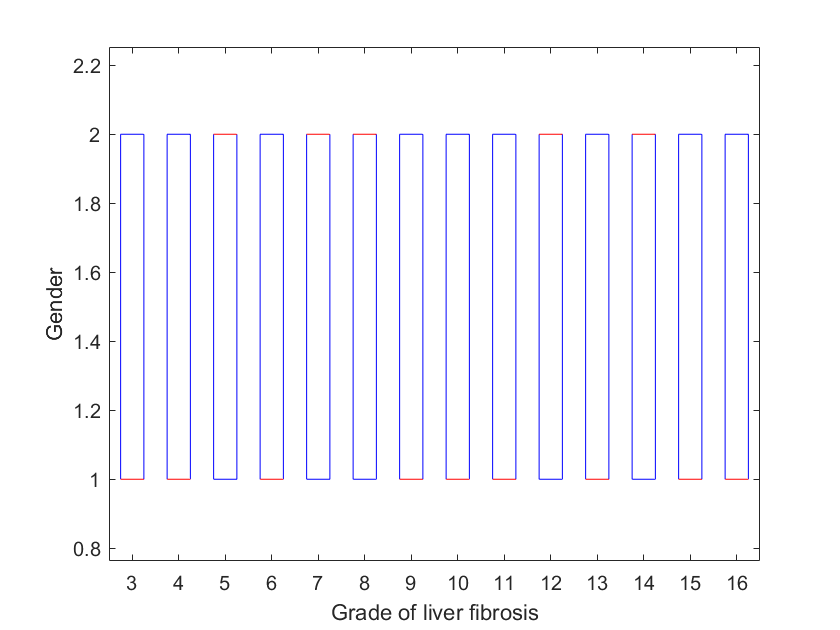

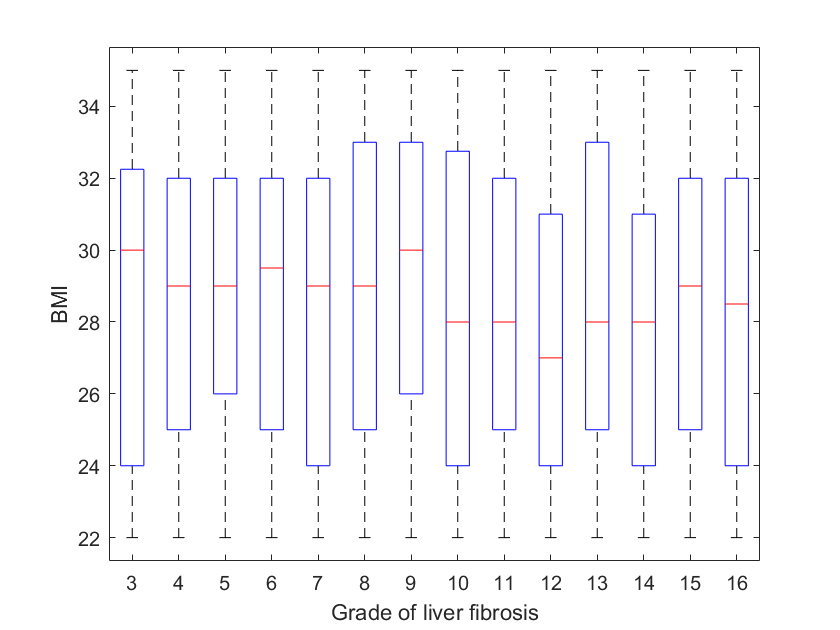

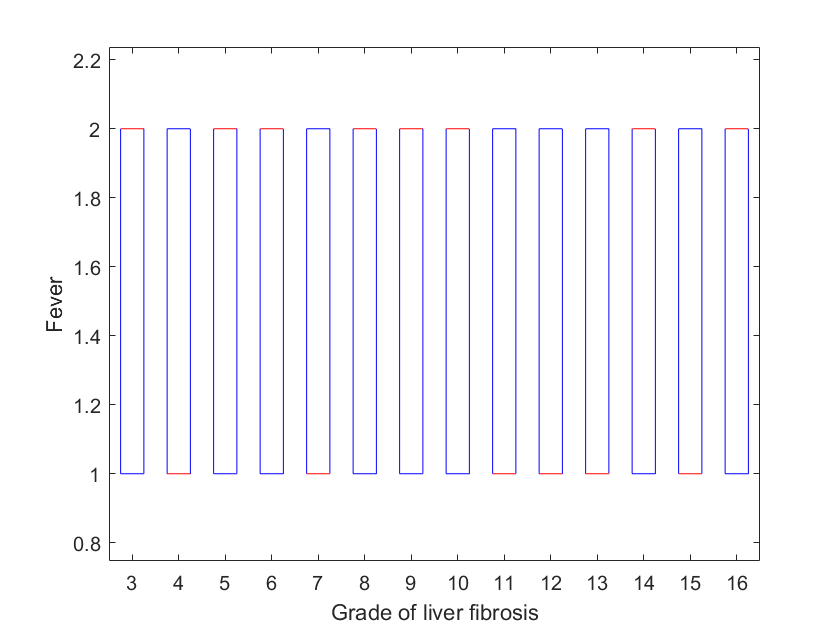

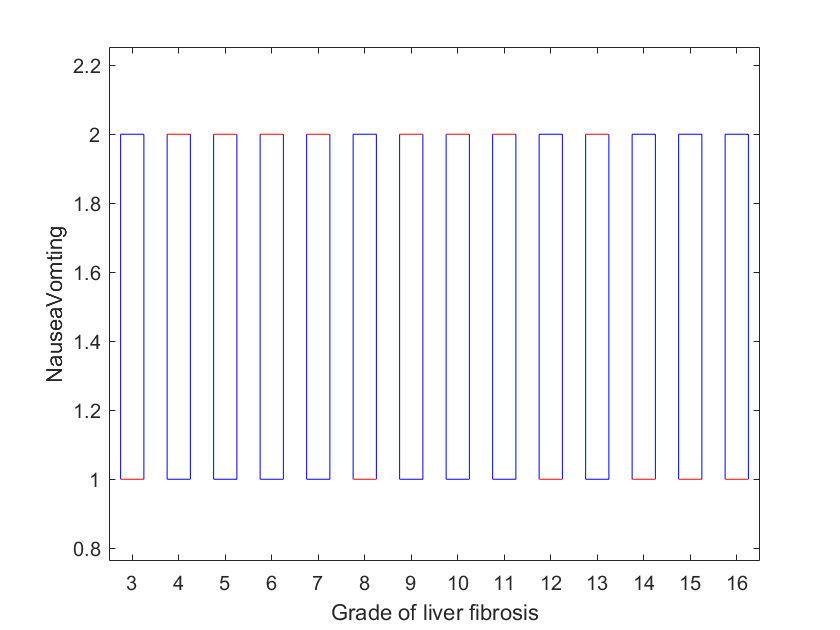

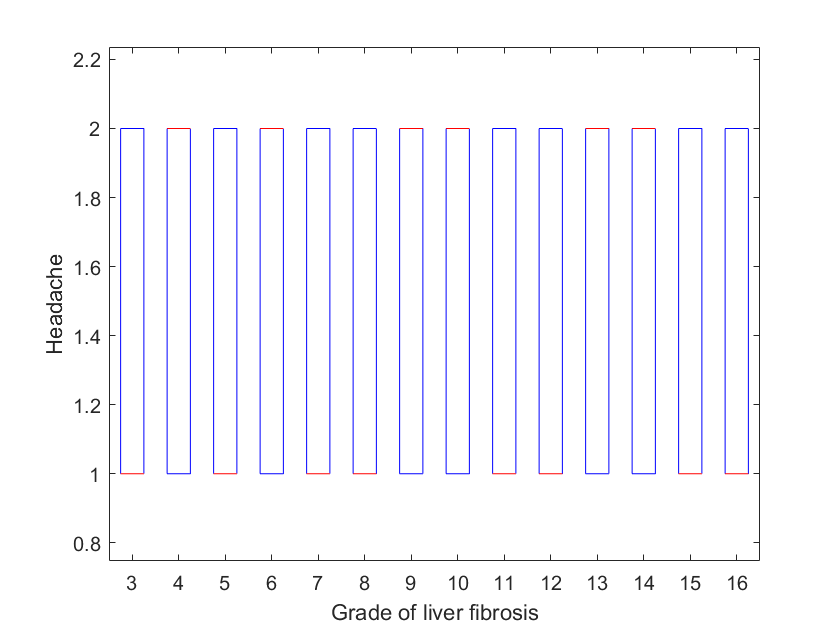

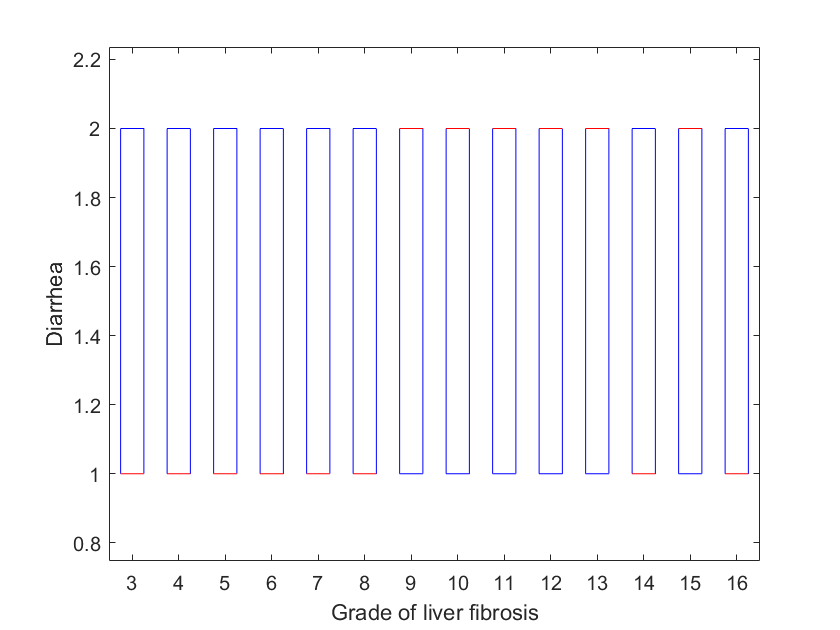

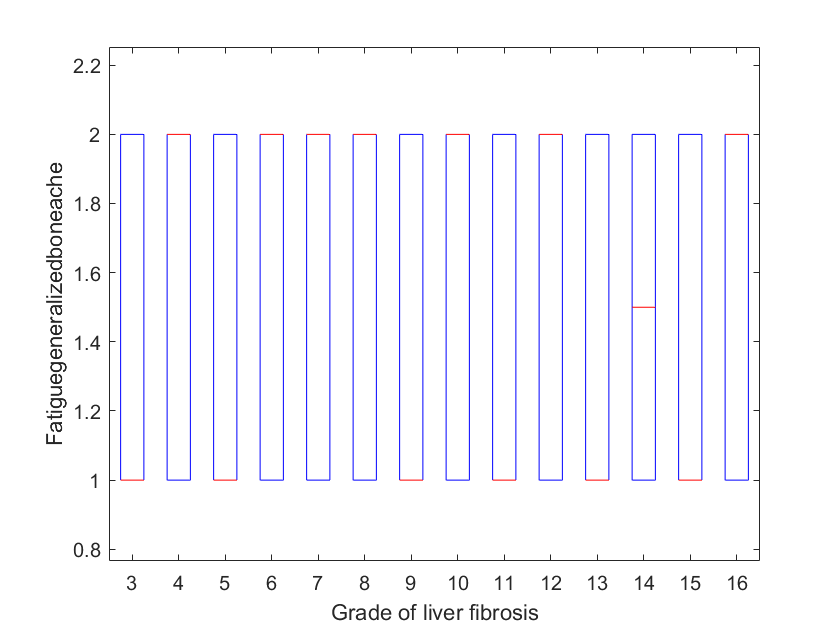

for z=1:27
    figure
    boxplot(HCV_array(:,z),HCV_array(:,end-1))
    xlabel('Grade of liver fibrosis')
    ylabel(HCV.Properties.VariableNames(z))
end

`From observing the boxplots`

[HCV_array_out, TF]=rmoutliers(HCV_array(:,[21,22,25]));
for i=1:1385
    if TF(i)==1
        HCV(i,:)=[];
        fprintf('Deleted row/Outlier data=%d\n',i)
    end
end

Deleted row/Outlier data=1
Deleted row/Outlier data=3
Deleted row/Outlier data=5
Deleted row/Outlier data=458


`Outliers from 2 valued variables must not be considered so do look for outliers in columns 2,4,5,6,7,8,9,10 and also in expected out in this case coz those are grades or stages 28,29. This should be similar to one above.`

[array_out,tf]=rmoutliers(HCV_array(:,[1,11:27]))

array_out =           46       12101     4429425          10      129367          91         123          95          75         113          57         123          44       40620      538635      637056      336804       31085
          49        6490     4794631          10      146457          43          64         109          80          88          48          77          33     1041941      449939      585688      744463      582301
          58       11785     3882456          15      131228          66         104         121          96          65          73         114          29     1157452     1086852           5           5           5
          42       11620     4747333          12      177261          78          57         113         118         107          84          80          28      325694     1034008      275095      214566      635157
          48        7335     4405941          11      216176         119         112          80         127          45

tf = 1385×1 logical array
   1
   0
   1
   0
   1
   0
   0
   0
   0
   0


**Yes, the output is same as expected. No more outliers in the data.**

HCV_array=table2array(HCV);

## Input and Output for analysis

HCV.Properties.VariableNames(end-1:end)={'Grade','Stage'}

HCV = 1381×29 table
    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       Grade    Stage
    ___    ______    ___    _____    _____________    

HCVin=HCV(:,1:end-2)

HCVin = 1381×27 table
    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF   
    ___    ______    ___    _____    _____________    ________    ________  

HCVout=HCV(:,end-1:end)

HCVout = 1381×2 table
    Grade    Stage
    _____    _____

      4        2  
      4        4  
     11        1  
      4        4  
     12        3  
      5        2  
      4        2  
     15        2  
     16        1  
      8        1  
      9        2  
      8        2  
     15        1  
      3        4  
      4        3  
      6        4  


## Studying dataset 

Varying valued variables

v=[1,3,11:27]

v =      1     3    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27


sv=zeros(length(v),5);
j=0

j = 0

for i=1:27
    if v(v==i)
        j=j+1;
        sv(j,1)=mean(HCV1.(i));
        sv(j,2)=std(HCV1.(i));
        sv(j,3)=median(HCV1.(i));
        sv(j,4)=range(HCV1.(i));
        sv(j,5)=corr(HCV1.(i),HCV1.(29));
    end
end
array2table(sv,'RowNames',HCV1.Properties.VariableNames([1,3,11:27]),"VariableNames",{'Mean','Std Dev','Median','Range','Correlation'})

ans = 19×5 table
                      Mean        Std Dev        Median        Range       Correlation
                   __________    __________    __________    __________    ___________

    Age                46.306        8.7854            46            29     -0.018499 
    BMI                28.602         4.076            29            13      -0.05645 
    WBC                7528.4        2667.6          7498          9110      0.017156 
    RBC            4.4222e+06    3.4621e+05    4.4385e+06     1.202e+06     0.0076778 
    HGB                 12.59        1.7135            13             5     0.0035003 
    Plat           1.5833e+05         38787    1.5792e+05    1.3345e+05      -0.01753 
    AS

ans = 705

Constant valued variables

c=[2,4:10]

c =      2     4     5     6     7     8     9    10


k=0

k = 0

v=zeros(length(c),2)

v =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


for i=2:10
    if c(c==i)
        k=k+1;
        v(k,1)=sum(HCV1.(i)(HCV1.(i)==1));
        v(k,2)=sum(HCV1.(i)(HCV1.(i)==2));
    end
end
males=sum(HCV1.Gender(HCV1.Gender==1))

males = 705

females=sum(HCV1.Gender(HCV1.Gender==2))

females = 1352

array2table(v,'RowNames',HCV1.Properties.VariableNames([2,4:10]),'VariableNames',{'Male/Absent','Female/Present'})

ans = 8×2 table
                                  Male/Absent    Female/Present
                                  ___________    ______________

    Gender                            705             1352     
    Fever                             668             1426     
    NauseaVomting                     686             1390     
    Headache                          696             1370     
    Diarrhea                          687             1388     
    Fatiguegeneralizedboneache        692             1378     
    Jaundice                          691             1380     
    Epigastricpain                    686             1390     


for i=28:29
    r(i-27,1)=range(HCV1.(i));
    r(i-27,2)=max(HCV1.(i));
    r(i-27,3)=min(HCV1.(i));
end
array2table(r,"RowNames",{'Grade','Stage'},"VariableNames",{'Range','Minimum','Maximum'})

ans = 2×3 table
             Range    Minimum    Maximum
             _____    _______    _______

    Grade     13        16          3   
    Stage      3         4          1   


grades=[min(HCV1.Grade):max(HCV1.Grade)]

grades =      3     4     5     6     7     8     9    10    11    12    13    14    15    16


stages=[min(HCV1.Stage):max(HCV1.Stage)]

stages =      1     2     3     4


For constant valued variables

grade1=HCV1(HCV1.Grade==3,:)

grade1 = 89×29 table
    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       Grade    Stage
    ___    ______    ___    _____    _____________    

s=size(grade1);

s =     89    29


f=0;

f = 0

m=0;

m = 0

for i=1:s(1)
    if grade1.(2)(i)==1
        m=m+1;
    elseif grade1.(2)(i)==2
        f=f+1;
    end
end
m

m = 45

f

f = 44

HCV1.(28)(1)

ans = 4

r =     89
    94
     0
     0
     0
     0
     0
     0
     0
     0


Gender distribution of cases with respect to grades

cr=zeros(16,3);
for j=1:1381
    for i=3:16
        if HCV1.(28)(j)==i
            cr(i,1)=cr(i,1)+1;
            if HCV1.(2)(j)==1
                cr(i,2)=cr(i,2)+1;
            elseif HCV1.(2)(j)==2
                cr(i,3)=cr(i,3)+1;
            end
        end
    end
end
array2table(cr,"VariableNames",{'Cases per grade','Male cases per grade','Female cases per grade'})

ans = 16×3 table
    Cases per grade    Male cases per grade    Female cases per grade
    _______________    ____________________    ______________________

            0                    0                        0          
            0                    0                        0          
           89                   45                       44          
           94                   51                       43          
           93                   44                       49          
          102                   55                       47          
           72                   33                       39          
           97                   48                       49          
          103                   61                       42          
           85                   46                       39          
          121                   64      

Fever distribution of cases with respect to grades

cr=zeros(16,3);
for j=1:1381
    for i=3:16
        if HCV1.(28)(j)==i
            cr(i,1)=cr(i,1)+1;
            if HCV1.(4)(j)==1
                cr(i,2)=cr(i,2)+1;
            elseif HCV1.(4)(j)==2
                cr(i,3)=cr(i,3)+1;
            end
        end
    end
end
array2table(cr,"VariableNames",{'Cases per grade','Fever absent','Fever present'})

ans = 16×3 table
    Cases per grade    Fever absent    Fever present
    _______________    ____________    _____________

            0                0               0      
            0                0               0      
           89               42              47      
           94               51              43      
           93               40              53      
          102               43              59      
           72               40              32      
           97               36              61      
          103               46              57      
           85               39              46      
          121               61              60      
          100               50              50      
           94               57              37      
          106               51              55      
          139               72  

- Females

- Males

- Fever absent

- Fever present

- Nausea present

- Nausea absent

- Headache

- Headache

- Dia

- Dia

- Fatigue

- Fatigue

grade=zeros(16,16);
for j=1:1381
    for i=3:16
        if HCV1.(28)(j)==i
            if HCV1.(2)(j)==1
                grade(1,i)=grade(1,i)+1;
            elseif HCV1.(2)(j)==2
                grade(2,i)=grade(2,i)+1;
            end
             if HCV1.(4)(j)==1
                grade(3,i)=grade(3,i)+1;
            elseif HCV1.(4)(j)==2
                grade(4,i)=grade(4,i)+1;
             end 
              if HCV1.(5)(j)==1
                grade(5,i)=grade(5,i)+1;
            elseif HCV1.(5)(j)==2
                grade(6,i)=grade(6,i)+1;
              end
              if HCV1.(6)(j)==1
                grade(7,i)=grade(7,i)+1;
            elseif HCV1.(6)(j)==2
                grade(8,i)=grade(8,i)+1;
              end
              if HCV1.(7)(j)==1
                grade(9,i)=grade(9,i)+1;
            elseif HCV1.(7)(j)==2
                grade(10,i)=grade(10,i)+1;
              end
              if HCV1.(8)(j)==1
                grade(11,i)=grade(11,i)+1;
            elseif HCV1.(8)(j)==2
                grade(12,i)=grade(12,i)+1;
              end
              if HCV1.(9)(j)==1
                grade(13,i)=grade(13,i)+1;
            elseif HCV1.(9)(j)==2
                grade(14,i)=grade(14,i)+1;
              end
              if HCV1.(10)(j)==1
                grade(15,i)=grade(15,i)+1;
            elseif HCV1.(10)(j)==2
                grade(16,i)=grade(16,i)+1;
            end
        end
    end
end
array2table(grade,"RowNames",{'Females','Males','Fever absent','Fever present','Nausea absent','Nausea present',....
    'Headache absent','Headache present','Diarrhea absent','Diarrhea present','Fatigue absent','Fatigue present',....
    'Jaundice absent','Jaundice present','Gastric pain absent','Gastric pain present'})

ans = 16×16 table
                            grade1    grade2    grade3    grade4    grade5    grade6    grade7    grade8    grade9    grade10    grade11    grade12    grade13    grade14    grade15    grade16
                            ______    ______    ______    ______    ______    ______    ______    ______    ______    _______    _______    _______    _______    _______    _______    _______

    Females                   0     

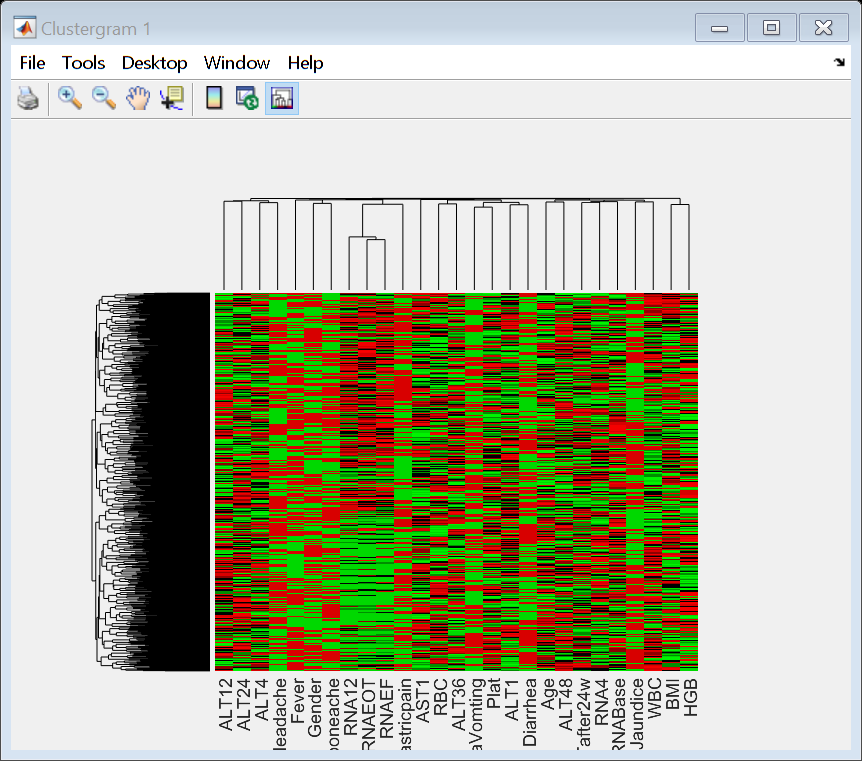

Clustergram object with 1381 rows of nodes and 27 columns of nodes.



col_names2=HCV1.Properties.VariableNames(1:end-2);
fram_cg_corr=clustergram(HCV1_array(:,1:end-2),...
    'RowLabels',HCV1.(28),....
    'ColumnLabels',col_names2,...
    'Standardize','column',...
    'RowPdist','correlation',...
    'ColumnPdist','correlation')

col_names2=HCV1.Properties.VariableNames(1:end-2);
HCV100=HCV1(1:50,:)

HCV100 = 50×29 table
    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       Grade    Stage
    ___    ______    ___    _____    _____________    

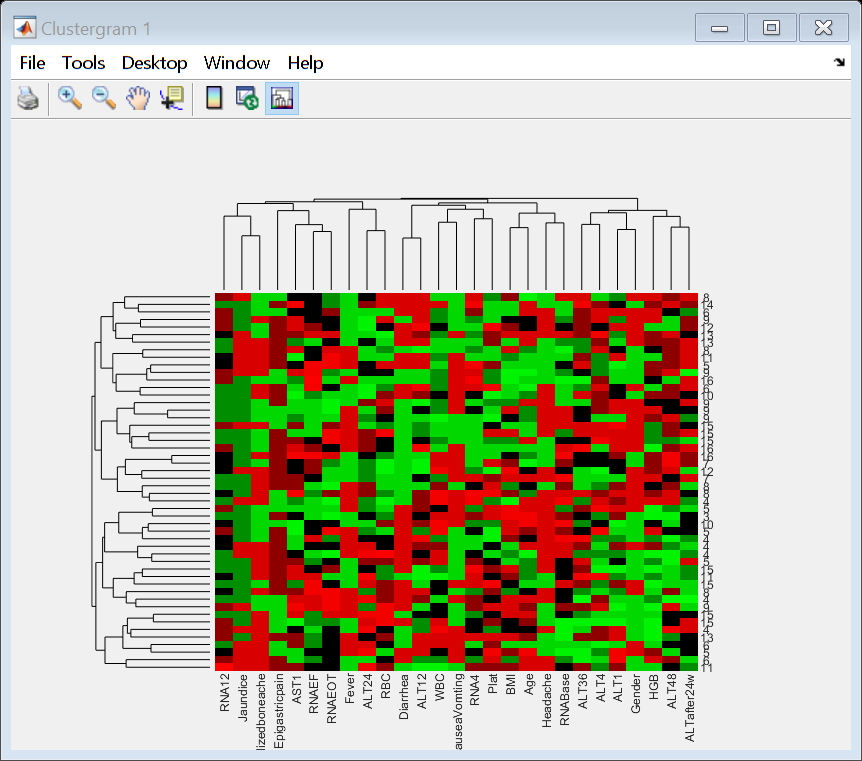

Clustergram object with 50 rows of nodes and 27 columns of nodes.



fram_cg_corr=clustergram(HCV1_array(1:50,1:end-2),...
    'RowLabels',HCV100.Grade,....
    'ColumnLabels',col_names2,...
    'Standardize','column',...
    'RowPdist','correlation',...
    'ColumnPdist','correlation')

col_names2=HCV1.Properties.VariableNames(1:end-2);
HCV100=HCV1(1:50,:)

HCV100 = 50×29 table
    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       Grade    Stage
    ___    ______    ___    _____    _____________    

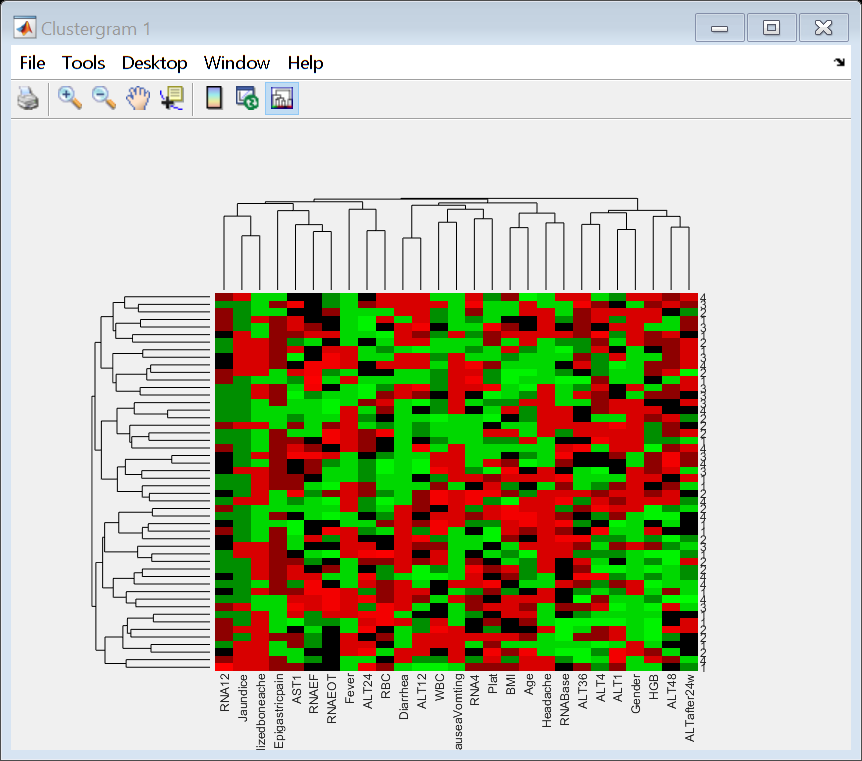

Clustergram object with 50 rows of nodes and 27 columns of nodes.



fram_cg_corr=clustergram(HCV1_array(1:50,1:end-2),...
    'RowLabels',HCV100.Stage,....
    'ColumnLabels',col_names2,...
    'Standardize','column',...
    'RowPdist','correlation',...
    'ColumnPdist','correlation')

class(HCV1.Grade)

ans = 'double'

HCVin=table2array(HCVin)

Error using table2array (line 34)
Input argument must be a table.

HCVout=table2array(HCVout)
[Xtrain,Ytrain,Xtest,Ytest]=trainTestSplit(HCVin,HCVout(:,1),0.7);
size(Xtrain)

k_values=2:967; % Exclude both histological values 
n=length(k_values);
s_score=zeros(n,1);

for i=1:n
   idx=kmeans(Xtrain,k_values(i),'Distance',"sqeuclidean");
    s=silhouette(Xtrain,idx);
    s_score(i)=mean(s); % Average silhouette values for clusters
end
table(k_values',s_score)

ans = 966×2 table
    Var1    s_score
    ____    _______

      2     0.27937
      3     0.24258
      4      0.2601
      5      0.2618
      6       0.272
      7      0.2938
      8     0.29406
      9     0.29885
     10     0.28981
     11      0.2847
     12     0.29453
     13     0.30284
     14      0.2972
     15     0.26974
     16     0.26991
     17     0.27801


k=find(s_score==max(s_score))+1

k = 967

fprintf('The optimal number of patient groups with k-means clustering using silhouette analysis is %d',k)

The optimal number of patient groups with k-means clustering using silhouette analysis is 967

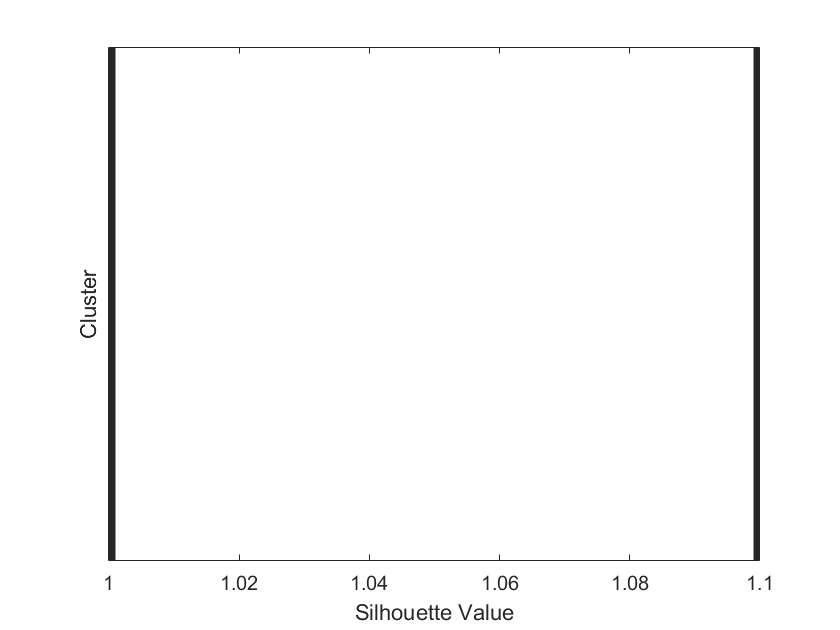

idx=kmeans(Xtrain,k);
silhouette(Xtrain,idx)

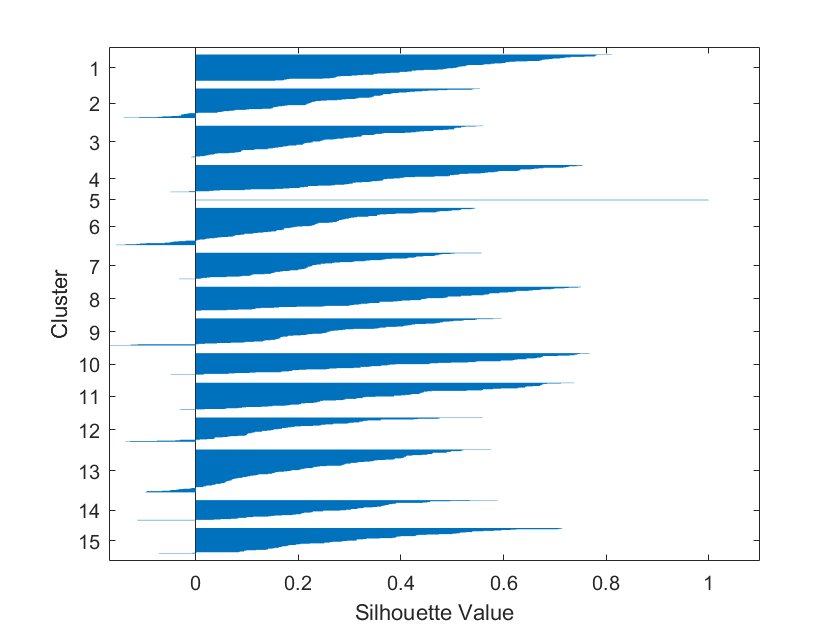

idx=kmeans(Xtrain,floor(sqrt(967)/2));
silhouette(Xtrain,idx)

idx=kmeans(Xtrain,3)

idx =      3
     2
     1
     1
     3
     2
     1
     1
     1
     2


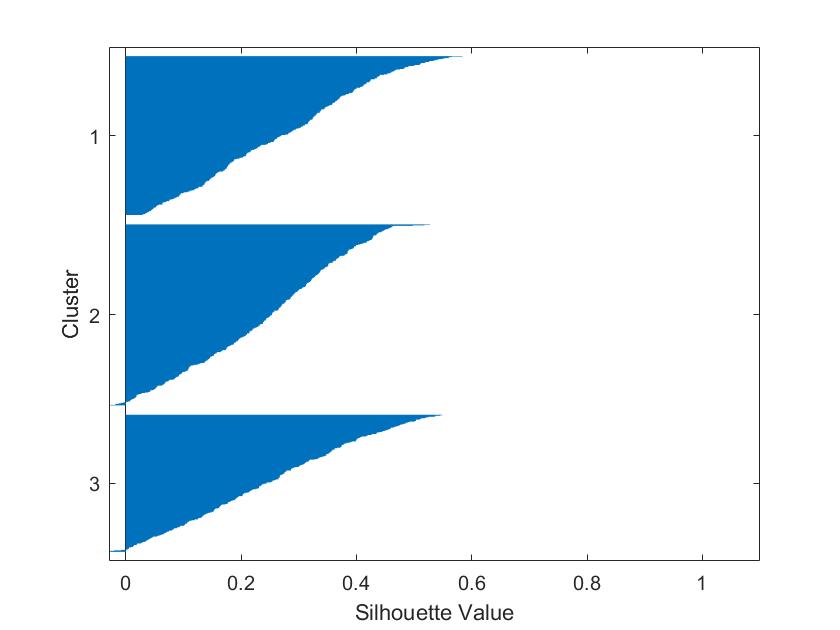

silhouette(Xtrain, idx)

[Xtrain,Ytrain,Xtest,Ytest]=trainTestSplit(HCV_array(:,11:27),HCV_array(:,28),0.7);
X=zscore(Xtrain)

X =     1.4264   -1.4236   -0.3571    1.3153    1.0900    0.6717    1.2504   -0.7742    0.5030    0.3889    0.0102    0.0917   -0.7158    1.6144   -1.0682   -1.1083   -1.0921
    0.3941    0.6454   -0.3571   -0.0494    1.7060   -1.4019   -0.0603    0.1075    1.1903    1.1442   -1.5189    0.7983    0.2568   -0.1005   -1.0682   -1.1083   -1.0921
   -1.2859    0.2815    0.8178   -0.1273   -1.4124   -1.5555    1.6623    0.3375    0.0067    0.8421    0.7747    0.9396    1.6697   -0.8394    1.0744   -0.4114    1.5146
   -1.5338    1.0190    0.8178   -0.2404   -0.7964   -1.3251    0.6512    0.0692    1.5721   -0.1020   -0.9837    1.0810    0.1249   -1.3354    0.7482    0.9721    1.4327
   -0.2780    0.2311    0.8178    0.4833    0.9745    0.6333   -0.9590   -1.4642    1.0757   -1.1972   -0.4485    1.3636   -1.2884   -0.4880   -0.1058    0.2364   -0.0177
   -0.3686    1.0914   -1.5320   -0.3162   -1.5279   -0.7491    0.9508   -0.1225    0.1594   -1.3105   -0.2574   -0.0496    1.2828   -0.4412 


[idx,C]=kmeans(X,13)

idx =     11
    11
     1
     4
    13
     8
    13
     4
    11
     5


C =    -0.4638   -0.6452   -0.1559   -0.6282   -0.4579   -0.4719   -0.0788    0.3249    0.0799   -0.1134    0.6024    0.4073    0.9379    0.3533    0.7291    0.5471    0.1607
    0.6114   -0.8050   -0.2161    0.0769   -0.4186   -0.5295   -0.0568   -0.7624   -0.5309    0.0390    0.1723    0.2481   -0.5705    0.4287    0.5231    0.7827    0.2875
   -0.4939    0.6779    0.0026    0.5574   -0.3674    0.5862   -0.0381    0.5440   -0.6416    0.5408    0.1241    0.2619   -0.8641    0.6007   -0.6091   -0.5675   -0.6007
   -0.4758   -0.0108    0.2131    0.1991   -0.4677   -0.7311   -0.0199    0.9414    0.3933   -0.0039   -0.5520   -0.1770   -0.3914   -0.3236    0.3970    0.6008    0.7375
    0.2736    0.1357   -0.5208   -0.4688   -0.6658    0.3657   -0.1567    0.3815   -0.1717    0.3332    0.5867    0.2168    0.8891    0.3949   -0.9989   -0.9588   -1.0325
   -0.2464   -0.0220    0.3181    0.0844    0.1327    0.4871   -0.3990   -0.3777    0.1166   -1.0315   -0.1433   -0.6655   -0.3858    0.6688 

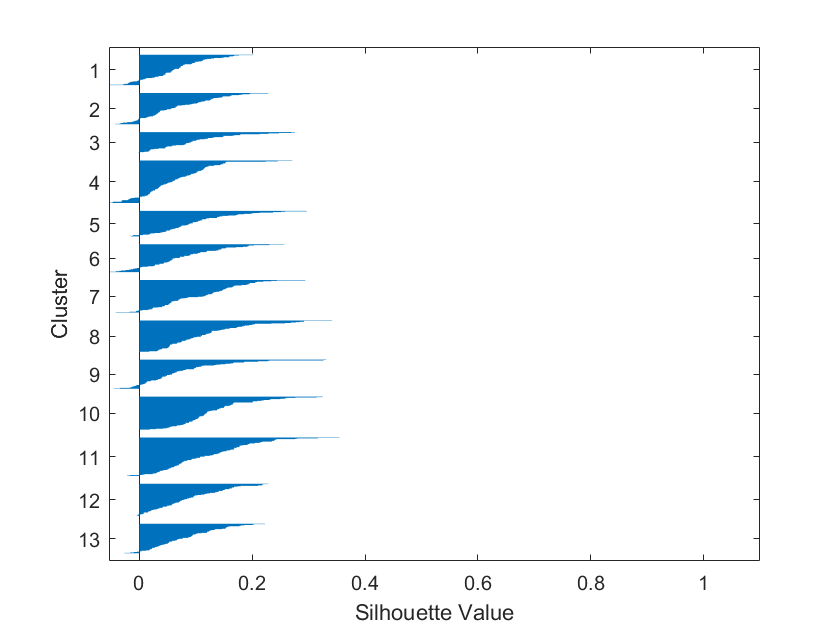

silhouette(X,idx)

%gscatter()

[Xtrain,Ytrain,Xtest,Ytest]=trainTestSplit(HCV_array(:,11:27),HCV_array(:,28),0.7);
X1=zscore(Xtrain)

X1 =     0.7923    1.3108    0.2324    0.7766   -0.9530   -0.3198    1.1915    1.1426    1.5240    1.4791   -1.3103   -0.9232   -0.1553    0.9120   -0.9016    0.2117    1.3840
    0.5752    0.7325   -0.3541   -1.6583    0.2510   -1.3945    1.3408    1.2948   -0.6682    0.7504   -1.0038   -0.0736   -0.3193   -0.9391   -1.0656   -1.1053   -1.1229
    0.9675    1.6453   -0.9406    0.7608    0.2121   -1.6632    1.3782    0.6098    0.9087   -1.2438    0.8730   -1.4895    0.3602    1.6370   -1.0656   -1.1053   -1.1229
    0.3383    1.6639   -0.3541    0.6108    1.0277    0.1792    1.1168    1.6374   -0.4759   -0.7069   -1.3486    0.3511    0.8567    0.3204    0.4450   -0.5533    1.6795
   -1.1846    1.2417    0.8190   -1.0571    1.6879   -0.5117   -0.0031   -1.3312   -0.2067   -1.5506    1.0262   -0.3568    1.0665    0.9824    0.1618    0.9618    0.0227
   -0.1494   -0.1351   -1.5272   -1.5666    1.3772   -0.0128   -0.2271    0.4575    1.1010   -1.3972    1.1028   -0.7816    0.0862    0.9740

X2=zscore(Xtest)

X2 =    -0.0743   -0.5055    0.8356   -1.2238    0.5897    0.0411   -1.2397    0.9489   -0.0436   -2.8498   -2.9190   -3.9767    0.1580    0.0639   -0.0101   -1.0453   -1.0117
   -0.4257    1.0831   -1.4702   -0.3112   -1.5174   -0.7395    0.9578   -0.1859    0.2191   -1.2663   -0.1996   -0.0349    1.2368   -0.4476    0.9231    1.7727    1.1749
   -1.4889    0.5352   -0.8938    0.7848    0.5897    0.8217   -0.6614   -1.4380    1.4201    0.4278    0.2914   -0.4572    0.1722    0.3527   10.7912    0.2377   -0.0998
    1.5643   -1.5718    1.4120   -0.7161   -0.6520    0.8217    1.4205    0.4402   -0.6441   -0.3456    1.1979   -0.5980    1.5591    1.3171   -0.9142   -1.0453   -1.0117
   -0.1081   -0.0482   -0.8938    1.5423    1.3423    1.1340   -0.1602    1.6533   -1.3947    0.5014   -1.1061    0.8098    0.1184   -1.4946    1.5555    0.3575    0.8895
    1.0739    0.5412   -0.3173   -0.2466    0.3640    0.0021   -1.1241    0.6750    0.5569    1.4589   -1.6348    1.6545   -0.0203    0.4042


IDX=knnsearch(X1,X2,'K',5,'Distance','seuclidean')

IDX =    246    23   482   626   213
   699   849   525   944   365
   357   210   546   211   601
   422   619   681    68   343
    90    19   436   375   826
   913   395   359   132   427
   667   135   389   848   415
   808    19   858   592    59
    42   435   743   732    46
   401   463   930    47   743


X1(IDX,:) 

ans =     0.1216   -1.7375    0.2324   -0.4747    0.4452   -0.1663   -0.4511    1.2568    1.6394   -1.5889   -1.1187   -1.4895   -0.3757    1.1148   -1.0656   -1.1053   -1.1229
   -0.9731    0.1507   -0.3541   -0.1159   -1.4967   -0.2431    1.4528   -0.9887    0.6010   -1.7040    0.1070   -1.0647   -0.2441    0.7763    1.2221    1.2564    1.3790
   -1.4264   -0.4615   -0.3541    0.4102    0.9112    1.4458    0.4449   -1.1409    1.6010    1.0572    0.9113   -0.6400    0.6066    0.6055    1.8410    0.6049    1.3275
    1.3758   -1.5052    0.8190   -0.9972   -1.6908    0.4478    1.0422    0.6098   -0.3605   -0.2850    0.7964    0.3511    1.3987   -0.4528   -1.0656   -1.1053   -1.1229
   -0.1913   -0.7227   -0.3541    0.7246    0.3675    0.0256   -0.1524    0.4956   -1.5912   -1.0137   -0.5442    0.3511    0.2474   -1.2286    1.1104   -0.7298   -0.0060
    0.3735    0.6298   -0.3541   -0.0408    1.7268   -1.4329   -0.0405    0.1150    1.1779    1.1339   -1.5401    0.7759    0.2642   -0.064

    X2

X2 =    -0.0743   -0.5055    0.8356   -1.2238    0.5897    0.0411   -1.2397    0.9489   -0.0436   -2.8498   -2.9190   -3.9767    0.1580    0.0639   -0.0101   -1.0453   -1.0117
   -0.4257    1.0831   -1.4702   -0.3112   -1.5174   -0.7395    0.9578   -0.1859    0.2191   -1.2663   -0.1996   -0.0349    1.2368   -0.4476    0.9231    1.7727    1.1749
   -1.4889    0.5352   -0.8938    0.7848    0.5897    0.8217   -0.6614   -1.4380    1.4201    0.4278    0.2914   -0.4572    0.1722    0.3527   10.7912    0.2377   -0.0998
    1.5643   -1.5718    1.4120   -0.7161   -0.6520    0.8217    1.4205    0.4402   -0.6441   -0.3456    1.1979   -0.5980    1.5591    1.3171   -0.9142   -1.0453   -1.0117
   -0.1081   -0.0482   -0.8938    1.5423    1.3423    1.1340   -0.1602    1.6533   -1.3947    0.5014   -1.1061    0.8098    0.1184   -1.4946    1.5555    0.3575    0.8895
    1.0739    0.5412   -0.3173   -0.2466    0.3640    0.0021   -1.1241    0.6750    0.5569    1.4589   -1.6348    1.6545   -0.0203    0.4042

[mode(Ytrain(IDX),2) Ytest]

ans =      4    13
     6    10
    11    11
     3     4
    11    12
    14     5
    11     4
     5    15
     5    16
     9     9


sum(mode(Ytrain(IDX),2)==Ytest)/length(Ytest)

ans = 0.0721

# Choosing important features for grade

h=HCV_array(:,1:end-2);
grade=HCV_array(:,end-1);

[b,dev,stats] = mnrfit(h, categorical(grade)); 

Ypred = mnrval(b,h)

Ypred =     0.1129    0.0841    0.0601    0.0584    0.0781    0.0636    0.0349    0.0529    0.0935    0.0373    0.1379    0.0337    0.0950    0.0575
    0.0594    0.1116    0.1170    0.1749    0.0641    0.0451    0.0783    0.0390    0.0424    0.0743    0.0938    0.0127    0.0779    0.0095
    0.1902    0.0324    0.0768    0.1739    0.0068    0.0006    0.0017    0.0090    0.4607    0.0169    0.0061    0.0029    0.0206    0.0013
    0.0536    0.0937    0.0700    0.0768    0.0367    0.0781    0.0548    0.0503    0.0353    0.0348    0.1616    0.1583    0.0285    0.0675
    0.0212    0.0913    0.0364    0.1025    0.0383    0.0549    0.0793    0.0659    0.0821    0.1317    0.0652    0.0633    0.1356    0.0323
    0.0622    0.1251    0.0208    0.0394    0.0307    0.0489    0.0678    0.0842    0.0603    0.0989    0.0649    0.1049    0.1085    0.0832
    0.0451    0.0689    0.0401    0.0654    0.0247    0.0770    0.1790    0.0806    0.0729    0.0669    0.0403    0.0923    0.0887    0.0581
    0

PV2=stats.p

PV2 =     0.4067    0.4443    0.1733    0.3283    0.8156    0.3368    0.0749    0.8447    0.2274    0.7964    0.5846    0.1227    0.7225
    0.1694    0.2333    0.3910    0.9965    0.4527    0.9866    0.3457    0.9151    0.0327    0.4466    0.0734    0.3364    0.6081
    0.6214    0.8415    0.4297    0.9678    0.3641    0.7327    0.3711    0.7689    0.9561    0.5443    0.4637    0.0317    0.7202
    0.7776    0.8429    0.4129    0.3847    0.8383    0.4620    0.0611    0.6466    0.4962    0.5012    0.9235    0.4680    0.4305
    0.9437    0.3048    0.6884    0.6084    0.2320    0.2001    0.7255    0.9945    0.6319    0.6243    0.0595    0.7838    0.4224
    0.9977    0.3341    0.3431    0.2800    0.1040    0.8200    0.8211    0.9042    0.7697    0.2238    0.1001    0.5744    0.3520
    0.4766    0.1358    0.8361    0.0071    0.5071    0.6945    0.1036    0.0989    0.9083    0.7692    0.0717    0.0595    0.2946
    0.7013    0.9505    0.7388    0.6884    0.9606    0.6571    0.6826    0.0

PV2mean=mean(PV2,2)

PV2mean =     0.4522
    0.4606
    0.6010
    0.5573
    0.5553
    0.5095
    0.3818
    0.5886
    0.6253
    0.5989


PV2median=median(PV2,2)

PV2median =     0.4067
    0.3910
    0.6214
    0.4962
    0.6243
    0.3520
    0.2946
    0.6840
    0.6487
    0.6550


t=[array2table(PV2median,'RowNames',HCV1.Properties.VariableNames(1:end-1)) array2table(PV2mean,'RowNames',HCV1.Properties.VariableNames(1:end-1))];
t=sortrows(t,'PV2mean','descend')

t = 28×2 table
                                  PV2median    PV2mean
                                  _________    _______

    ALT12                          0.77231     0.71471
    ALTafter24w                    0.74441     0.67353
    AST1                           0.66906     0.64161
    ALT4                           0.74836     0.64132
    Jaundice                       0.64874     0.62527
    BMI                            0.62139     0.60101
    Epigastricpain                   0.655      0.5989
    Plat                           0.72934     0.59393
    RNAEF                          0.52414     0.58971
    Fatiguegeneralizedboneache     0.68403     0.58865
    Fever                          0.49618     0.55734
    Na

let's consider 0.5 as the threshold. Thus, 15 features are more important.

impfea=t.Properties.RowNames(1:6)

impfea = 6×1 cell array
    {'ALT12'      }
    {'ALTafter24w'}
    {'AST1'       }
    {'ALT4'       }
    {'Jaundice'   }
    {'BMI'        }


HCVimp=table2array(HCV1(:,impfea))

HCVimp =     75    44    91    95     2    29
   107     5   113    95     1    33
    48    30    99    67     2    32
    96    29    66   121     2    22
   127    39   119    80     1    30
   102    45    93    55     1    23
   127    30    55    72     1    30
    74    33   103   111     2    24
    52    45    75    93     1    22
    53    26    97    66     1    25


Actualgrade=HCV1_array(:,end-1);
Grade=HCV1_array(:,end-1)-(3*ones(1381,1));
ratio=0.70;
[Xtrain1, Ytrain1, Xtest1, Ytest1]=trainTestSplit(HCVimp,Grade,ratio);
[b,dev,stats] = mnrfit(Xtrain1, categorical(Ytrain1)); 
Ypred = mnrval(b,Xtest1)

Ypred =     0.0905    0.0570    0.0534    0.0615    0.0525    0.0963    0.0919    0.0487    0.0924    0.0611    0.0856    0.0476    0.1138    0.0476
    0.0525    0.0425    0.0915    0.1049    0.0632    0.1126    0.0659    0.0583    0.0607    0.0581    0.0600    0.0530    0.1185    0.0581
    0.0748    0.0391    0.0631    0.1091    0.0618    0.1180    0.0663    0.0500    0.0842    0.0865    0.0477    0.0652    0.0858    0.0483
    0.0736    0.0477    0.0675    0.0821    0.0676    0.0854    0.0425    0.0822    0.0449    0.0937    0.0413    0.0826    0.1301    0.0589
    0.0449    0.0922    0.0782    0.0840    0.0636    0.0969    0.0491    0.0534    0.0491    0.0957    0.0710    0.0695    0.0793    0.0729
    0.0497    0.0554    0.0621    0.0798    0.0537    0.0930    0.0700    0.0646    0.1005    0.0673    0.0541    0.0971    0.0877    0.0648
    0.0834    0.0324    0.0815    0.1067    0.0726    0.0920    0.0656    0.0654    0.0623    0.0601    0.0455    0.0448    0.1404    0.0473
    0

%Use five folds cross validation
x1=HCVimp

x1 =     75    44    91    95     2    29
   107     5   113    95     1    33
    48    30    99    67     2    32
    96    29    66   121     2    22
   127    39   119    80     1    30
   102    45    93    55     1    23
   127    30    55    72     1    30
    74    33   103   111     2    24
    52    45    75    93     1    22
    53    26    97    66     1    25


y1=Grade

y1 =      1
     1
     8
     1
     9
     2
     1
    12
    13
     5


fold=10

fold = 10

index1=crossvalind('kfold',size(Xtrain1,1),fold);
accuracy1_=zeros(1,fold);
precision1_=zeros(1,fold);
recall1_=zeros(1,fold);
mae1=zeros(1,fold);
rcorr1=zeros(1,fold);
%Model 1
for i=1:fold
    test=(index1==i);
    train=~test;
    Xtrain1=x1(train,:);
    Xtest1=x1(test,:);
    Ytrain1=y1(train,:);
    Ytest1=y1(test,:);
    
    %Linear regression model
    b_1=mnrfit(Xtrain1,categorical(Ytrain1));
    a_1=mnrval(b_1,Xtest1);
    [r,c]=size(a_1);
    %Consider the maximum of given disease severities
    prediction_1=zeros(r,1);
    for j=1:r
        [k, idk]=maxk(a_1(j,:),1);
        prediction_1(j)=idk;
    end
    
    % For model accuracy
    accuracy1_(i)=sum(prediction_1==Ytest1)/length(prediction_1);
    precision1_(i)=sum(prediction_1==1 & Ytest1==1)/sum(prediction_1==1);
    recall1_(i)=sum(prediction_1==1 & Ytest1==1)/sum(Ytest1==1);
    mae1(i)=mean(abs(prediction_1-Ytest1));
    rcorr1(i)=corr(prediction_1,Ytest1);
end

accuracy1_

accuracy1_ =     0.0412    0.0833    0.1042    0.0206    0.0625    0.0722    0.0412    0.0722    0.0722    0.0722


precision1_

precision1_ =      0     0   NaN   NaN     0   NaN   NaN     0     0   NaN


mae1

mae1 =     4.9485    4.8021    4.0521    5.0103    4.9583    5.5567    5.7113    5.7732    5.5052    5.3608


# Choosing important features for stage

h=zscore(HCV_array(:,1:end-2));
grade=HCV_array(:,end);

[b,dev,stats] = mnrfit(h, categorical(grade)); 
Ypred = mnrval(b,h)

Ypred =     0.1200    0.3517    0.1816    0.3468
    0.3187    0.2960    0.2666    0.1187
    0.1006    0.3484    0.0978    0.4532
    0.1648    0.2056    0.3355    0.2941
    0.2731    0.1661    0.2847    0.2761
    0.3266    0.1566    0.1691    0.3476
    0.3715    0.1267    0.2178    0.2839
    0.1869    0.2227    0.2715    0.3190
    0.1838    0.1177    0.3720    0.3265
    0.2835    0.2335    0.2619    0.2212


PV2=stats.p

PV2 =     0.4638    0.2275    0.9373
    0.5336    0.0536    0.2395
    0.7425    0.4704    0.0594
    0.1281    0.0006    0.1832
    0.1659    0.3380    0.2050
    0.1122    0.2572    0.8229
    0.8698    0.8891    0.9131
    0.6120    0.5858    0.7511
    0.3824    0.6569    0.4554
    0.3401    0.3873    0.5283


PV2mean=mean(PV2,2)

PV2mean =     0.5428
    0.2755
    0.4241
    0.1040
    0.2363
    0.3974
    0.8907
    0.6496
    0.4982
    0.4186


PV2median=median(PV2,2)

PV2median =     0.4638
    0.2395
    0.4704
    0.1281
    0.2050
    0.2572
    0.8891
    0.6120
    0.4554
    0.3873


t=[array2table(PV2median,'RowNames',HCV1.Properties.VariableNames(1:end-1)) array2table(PV2mean,'RowNames',HCV1.Properties.VariableNames(1:end-1))];
t=sortrows(t,'PV2median','descend')

t = 28×2 table
                                  PV2median    PV2mean
                                  _________    _______

    ALT24                          0.91381      0.8677
    Diarrhea                       0.88912     0.89068
    ALT36                          0.73251     0.76672
    ALT48                          0.72298     0.73036
    WBC                            0.70992     0.50284
    Fatiguegeneralizedboneache     0.61202     0.64963
    HGB                            0.57533       0.574
    RNA4                           0.48761     0.37102
    BMI                            0.47042     0.42412
    Age                            0.46382     0.54285
    Jaundice                       0.45536     0.49824
    AS

let's consider 0.5 as the threshold. Thus, 15 features are more important.

impfea=t.Properties.RowNames(1:7)

impfea = 7×1 cell array
    {'ALT24'                     }
    {'Diarrhea'                  }
    {'ALT36'                     }
    {'ALT48'                     }
    {'WBC'                       }
    {'Fatiguegeneralizedboneache'}
    {'HGB'                       }


HCVimp=table2array(HCV1(:,impfea))

HCVimp =          113           1          57         123       12101           2          10
         116           2           5           5        4178           1          12
         120           1          94          90        3661           2          11
          65           1          73         114       11785           2          15
          45           2          96          53        7335           1          11
          97           2         122          39       10480           2          12
          81           2         125          43        6681           1          12
          53           1         123         101        4437           2          12
          46           1          46          59        6052           1          13
          95           1          55         104        9279           2          13


HCVimp=zscore(HCVimp)

HCVimp =     1.1171   -1.0047   -0.9949    1.5017    1.7141    1.0018   -1.5116
    1.2315    0.9946   -2.9693   -3.0063   -1.2560   -0.9975   -0.3444
    1.3842   -1.0047    0.4100    0.2410   -1.4498    1.0018   -0.9280
   -0.7144   -1.0047   -0.3873    1.1579    1.5957    1.0018    1.4063
   -1.4775    0.9946    0.4860   -1.1726   -0.0725   -0.9975   -0.9280
    0.5066    0.9946    1.4732   -1.7074    1.1065    1.0018   -0.3444
   -0.1039    0.9946    1.5871   -1.5546   -0.3177   -0.9975   -0.3444
   -1.1723   -1.0047    1.5112    0.6612   -1.1589    1.0018   -0.3444
   -1.4394   -1.0047   -1.4126   -0.9433   -0.5535   -0.9975    0.2392
    0.4303   -1.0047   -1.0708    0.7758    0.6563    1.0018    0.2392


Grade=HCV1_array(:,end);
ratio=0.70;
[Xtrain1, Ytrain1, Xtest1, Ytest1]=trainTestSplit(HCVimp,Grade,ratio);
[b,dev,stats] = mnrfit(Xtrain1, categorical(Ytrain1)); 
Ypred = mnrval(b,Xtest1)

Ypred =     0.2178    0.2981    0.2506    0.2336
    0.2597    0.2662    0.2626    0.2115
    0.2415    0.2573    0.2400    0.2613
    0.2575    0.2596    0.2546    0.2282
    0.2572    0.2155    0.2221    0.3053
    0.2616    0.2492    0.2605    0.2286
    0.2632    0.2245    0.2293    0.2830
    0.2409    0.2541    0.2361    0.2689
    0.2571    0.2015    0.2173    0.3241
    0.3054    0.2219    0.1974    0.2753


Ytest1

Ytest1 =      2
     1
     4
     2
     4
     4
     2
     1
     1
     3


%Use five folds cross validation
x1=HCVimp

x1 =     1.1171   -1.0047   -0.9949    1.5017    1.7141    1.0018   -1.5116
    1.2315    0.9946   -2.9693   -3.0063   -1.2560   -0.9975   -0.3444
    1.3842   -1.0047    0.4100    0.2410   -1.4498    1.0018   -0.9280
   -0.7144   -1.0047   -0.3873    1.1579    1.5957    1.0018    1.4063
   -1.4775    0.9946    0.4860   -1.1726   -0.0725   -0.9975   -0.9280
    0.5066    0.9946    1.4732   -1.7074    1.1065    1.0018   -0.3444
   -0.1039    0.9946    1.5871   -1.5546   -0.3177   -0.9975   -0.3444
   -1.1723   -1.0047    1.5112    0.6612   -1.1589    1.0018   -0.3444
   -1.4394   -1.0047   -1.4126   -0.9433   -0.5535   -0.9975    0.2392
    0.4303   -1.0047   -1.0708    0.7758    0.6563    1.0018    0.2392


y1=Grade

y1 =      2
     4
     1
     4
     3
     2
     2
     2
     1
     1


fold=10

fold = 10

index1=crossvalind('kfold',size(Xtrain1,1),fold);
accuracy1_=zeros(1,fold);
precision1_=zeros(1,fold);
recall1_=zeros(1,fold);
mae1=zeros(1,fold);
rcorr1=zeros(1,fold);
%Model 1
for i=1:fold
    test=(index1==i);
    train=~test;
    Xtrain1=x1(train,:);
    Xtest1=x1(test,:);
    Ytrain1=y1(train,:);
    Ytest1=y1(test,:);
    
    %Linear regression model
    b_1=mnrfit(Xtrain1,categorical(Ytrain1));
    a_1=mnrval(b_1,Xtest1);
    [r,c]=size(a_1);
    %Consider the maximum of given disease severities
    prediction_1=zeros(r,1);
    for j=1:r
        [k, idk]=maxk(a_1(j,:),1);
        prediction_1(j)=idk;
    end
    
    % For model accuracy
    accuracy1_(i)=sum(prediction_1==Ytest1)/length(prediction_1);
    precision1_(i)=sum(prediction_1==1 & Ytest1==1)/sum(prediction_1==1);
    recall1_(i)=sum(prediction_1==1 & Ytest1==1)/sum(Ytest1==1);
    mae1(i)=mean(abs(prediction_1-Ytest1));
    rcorr1(i)=corr(prediction_1,Ytest1);
end

accuracy1_

accuracy1_ =     0.2680    0.2474    0.2680    0.2268    0.2990    0.2268    0.2083    0.2708    0.2188    0.1340


precision1_

precision1_ =     0.2667    0.1875    0.2121    0.1579    0.4000    0.2778    0.2500    0.3333    0.2083    0.1034


mae1

mae1 =     1.3711    1.2784    1.3402    1.2474    1.2165    1.4845    1.3854    1.3333    1.3750    1.5670



%Lasso Regression Model
[b3, Fit3] = lasso(Xtrain1,Ytrain1,'CV',5)

b3 =     0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0035    0.0034    0.0034    0.0034    0.0034    0.0033    0.0033    0.0033    0.0033    0.0032    0.0032    0.0031    0.0031    0.0030
   -0.0581   -0.0581   -0.0581   -0.0581   -0.0581   -0.0581   -0.0581   -0.0581   -0.0581   -0.0581   -0.0581   -0.0581   -0.0581   -0.0581   -0.0581   -0.0581   -0.0581   -0.0581   -0.0580   -0.0580   -0.0580   -0.0580   -0.0580   -0.0580   -0.0580   -0.0580   -0.0580   -0.0580   -0.0580   -0.0580   -0.0580   -0.0580   -0.0580   -0.0580   -0.0580   -0.0579   -0.0579   -0.0579   -0.0579   -0.0579   -0.0579   -0.0578   -0.0578   -0.0578   -0.0578   -0.0577   -0.0577   -0.0577   -0.0576   -

Fit3 = struct with fields:
         Intercept: [1×100 double]
            Lambda: [1×100 double]
             Alpha: 1
                DF: [7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 6 6 6 6 6 6 6 6 6 6 6 6 6 6 6 6 5 5 5 5 5 3 3 2 2 2 2 1 1 1 0]
               MSE: [1×100 double]
    PredictorNames: {}
                SE: [1×100 double]
      LambdaMinMSE: 0.0588
         Lambda1SE: 0.0588
       IndexMinMSE: 100
          Index1SE: 100


b3_lasso=b3(:,Fit3.IndexMinMSE)

b3_lasso =      0
     0
     0
     0
     0
     0
     0


ypred_lasso3=Xtest1*b3_lasso + Fit3.Intercept(Fit3.IndexMinMSE)

ypred_lasso3 =     2.5218
    2.5218
    2.5218
    2.5218
    2.5218
    2.5218
    2.5218
    2.5218
    2.5218
    2.5218


MAE_lasso3=mean(abs(ypred_lasso3-Ytest1))

MAE_lasso3 = 0.9619

[R_lasso3 pv_lasso3]=corr(ypred_lasso3,Ytest1)

R_lasso3 = 1.3518e-16

pv_lasso3 = 1.0000